# EEG Data Preprocessing

## Loading Dataset

% Initialize Data Parameters

fs = 256; % sample rate in Hz
testNodes = ["Cz","F4"];
H_CzF4 = EEGData(FC(1:6),testNodes,fs);
A_CzF4 = EEGData(FADHD(1:6),testNodes,fs);

H_Test1 = H_CzF4.Task(1);
A_Test1 = A_CzF4.Task(1);

H_subject = subject(1,1);
A_subject = subject(1,0);

H_subject.Data = H_Test1.getSubjectData(H_subject.Id,"Cz");

A_subject.Data = A_Test1.getSubjectData(A_subject.Id,"Cz");


## EDA and Bad Data Removal

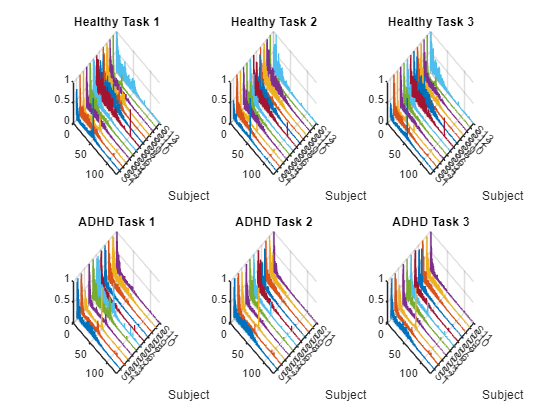

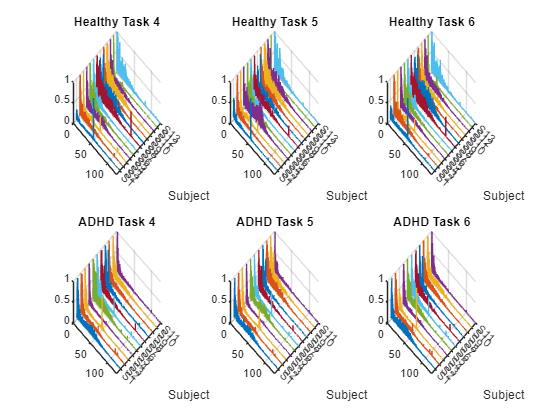

fftplot = figure;
fftplot2 = figure;
for i = 1:(H_CzF4.Ntests/2)
    figure(fftplot);
    subplot(2,3,i)
    subjectComparisonPlot(H_CzF4.Task(i));
    title("Healthy Task "+string(i));
    subplot(2,3,i+3)
    subjectComparisonPlot(A_CzF4.Task(i));
    title("ADHD Task "+string(i))

    figure(fftplot2);
    subplot(2,3,i)
    subjectComparisonPlot(H_CzF4.Task(i+3));
    title("Healthy Task "+string(i+3));
    subplot(2,3,i+3)
    subjectComparisonPlot(A_CzF4.Task(i+3));
    title("ADHD Task "+string(i+3))    
end

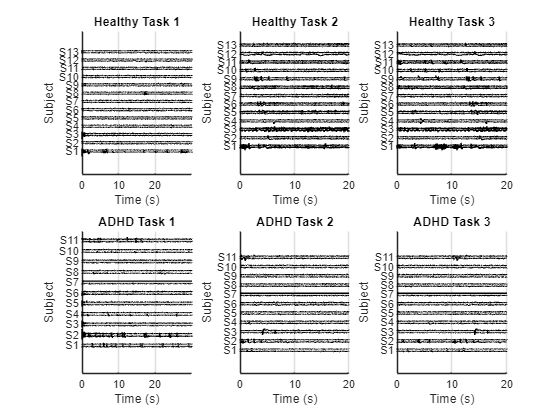

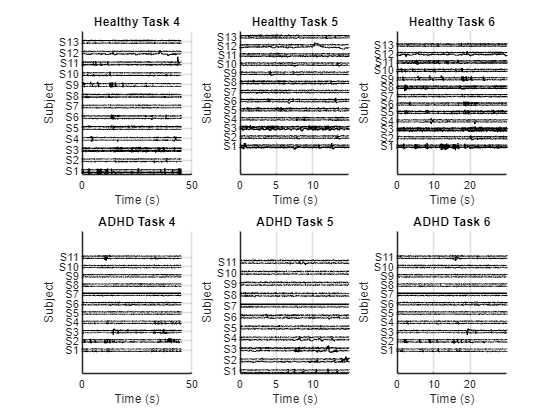

stack1 = figure;
stack2 = figure;
for i = 1:(H_CzF4.Ntests/2)
    figure(stack1);
    subplot(2,3,i)
    plotStackedEEG(H_CzF4.Task(i));
    title("Healthy Task "+string(i));
    subplot(2,3,i+3)
    plotStackedEEG(A_CzF4.Task(i));
    title("ADHD Task "+string(i))

    figure(stack2);
    subplot(2,3,i)
    plotStackedEEG(H_CzF4.Task(i+3));
    title("Healthy Task "+string(i+3));
    subplot(2,3,i+3)
    plotStackedEEG(A_CzF4.Task(i+3));
    title("ADHD Task "+string(i+3))    
end

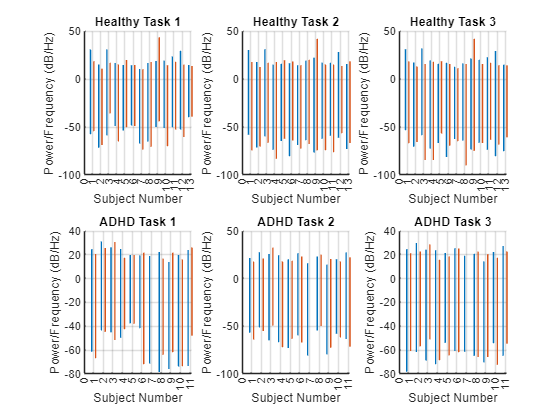

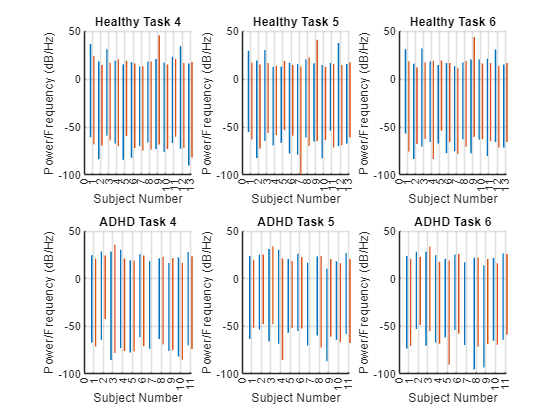

psd1 = figure;
psd2 = figure;
for i = 1:(H_CzF4.Ntests/2)
    figure(psd1);
    subplot(2,3,i)
    cmpPSD(H_CzF4.Task(i),[0,40]);
    title("Healthy Task "+string(i));
    subplot(2,3,i+3)
    cmpPSD(A_CzF4.Task(i),[0,40]);
    title("ADHD Task "+string(i))

    figure(psd2);
    subplot(2,3,i)
    cmpPSD(H_CzF4.Task(i+3),[0,40]);
    title("Healthy Task "+string(i+3));
    subplot(2,3,i+3)
    cmpPSD(A_CzF4.Task(i+3),[0,40]);
    title("ADHD Task "+string(i+3))    
end

## Data Filtering

The first step in processing the data   

raw = H_subject.Data;
padlen = 256;
padded = [flip(raw(1:padlen)) raw flip(raw(end-padlen+1:end))];


H_HPfiltered = filtfilt(ButterHP,padded);

H_Combofiltered = filtfilt(ButterBS,filtfilt(ButterHP,padded));
H_Combofiltered = H_Combofiltered(padlen+1:end-padlen);
H_HPfiltered =H_HPfiltered(padlen+1:end-padlen);

signals = [H_Combofiltered; H_subject.Data];
times = H_Test1.times(1:end-1);
names = ["High*Band","Raw"];

plotSignals(fs, signals, times, names);

